# Showcasing current DMD class capabilities

#### Data preparation

load("..\data\imgV2.mat");
perfCm = buildcmap('yrk');
barCm = buildcmap('bwr');
fs = 50; %Hz
res = 32;

load("F:\data\VALIDEIT13\eit\MIK_P_75_IV\eitV2.mat");
imgV2 = eit.ImgRaw;
perfCm = buildcmap('yrk');
barCm = buildcmap('bwr');
fs = 50; %Hz
res = 64;

% Organize the data into "snapshots": spatial is rows, time is columns
% Restrict data window

xStart = 1000;
xEnd = 1500;

stdMap = std(imgV2,[],3);
imgFilt = imgV2 .* repmat(stdMap > max(stdMap(:)) * 0.25, 1, 1, size(imgV2, 3));

t = (0:(size(flatImg,2)-1))'/fs;

Unrecognized function or variable 'flatImg'.

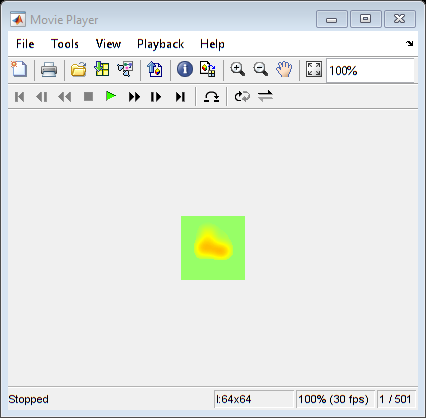

% Select heart and lung pixels
img = imgFilt(:,:,xStart:xEnd);

heartPix = [10,26];
lungPix = [30,20];
% lungPixR = [31,43];
% 
% heartSig = squeeze(img(heartPix(1),heartPix(2),:));
% lungSigL = squeeze(img(lungPixL(1),lungPixL(2),:));
% lungSigR = squeeze(img(lungPixR(1),lungPixR(2),:));

% heartPix = [10,16];
% lungPix = [16,20];

heartSig = squeeze(img(heartPix(1),heartPix(2),:));
lungSig = squeeze(img(lungPix(1),lungPix(2),:));

% Preview of what the real data looks like
playVideo(img);

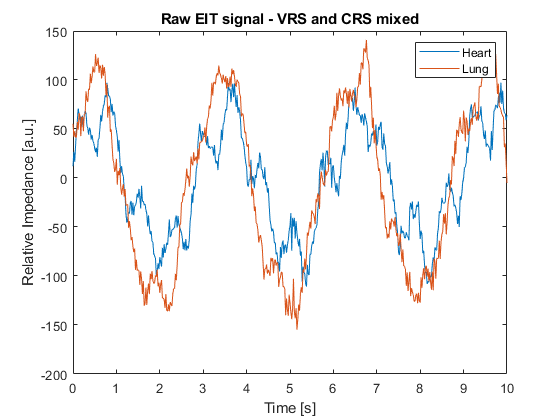

tSig = (0:(size(img,3)-1))'/fs;
figure; plot(tSig, [heartSig,lungSig]);
% figure; plot(tSig, [heartSig,lungSigL,lungSigR]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart","Lung"]);
% legend(["Heart","Lung Left","Lung Right"]);
title("Raw EIT signal - VRS and CRS mixed");

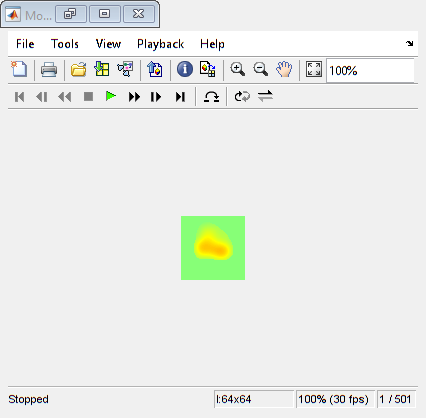

% Low-pass filter data
% Design low-pass filter
% Filter parameters
N    = 2*fs;     % Choose 2*Fs in order to properly filter signals down to f=0.5Hz
Fc   = 15;    % Cutoff Frequency [Hz]
flag = 'scale';     % Sampling Flag

win = hamming(N+1); % Create the window vector for the design algorithm.
b  = fir1(N, Fc/(fs/2), 'low', win, flag); % Calculate the coefficients using the FIR1 function.

% Apply low-pass filter
imgFlat = reshape(img,size(img,1)*size(img,2),[]);
imgFlatFilt = filtfilt(b,1,imgFlat');
imgFlatFilt = (imgFlatFilt - repmat(mean(imgFlatFilt,1,'omitnan'),size(imgFlatFilt,1),1));% ./ repmat(std(imgFlatFilt,[],1,'omitnan'),size(imgFlatFilt,1),1); 
imgLow = reshape(imgFlatFilt',size(img,1),size(img,2),[]);

heartSig = squeeze(imgLow(heartPix(1),heartPix(2),:));
lungSig = squeeze(imgLow(lungPix(1),lungPix(2),:));

% Preview of what the real data looks like
playVideo(imgLow);

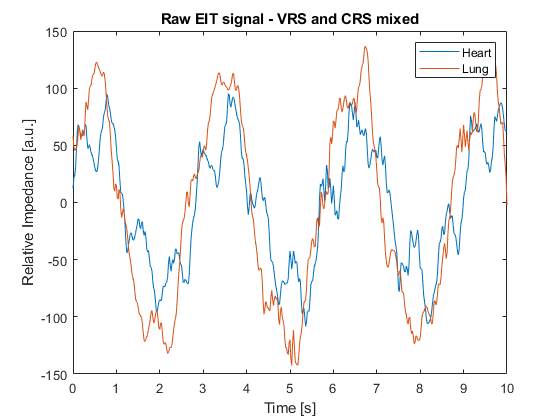

tSig = (0:(size(imgLow,3)-1))'/fs;
figure; plot(tSig, [heartSig,lungSig]);
% figure; plot(tSig, [heartSig,lungSigL,lungSigR]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart","Lung"]);
% legend(["Heart","Lung Left","Lung Right"]);
title("Raw EIT signal - VRS and CRS mixed");

img = imgLow;
flatImg = reshape(imgLow,res*res,[]);
X = flatImg(:,1:end-2);
X(isnan(X)) = 0;
Y = flatImg(:,2:end-1);
Y(isnan(Y)) = 0;

#### Simple DMD

% Initialize DMD class and properties
dmd = DMD();
rank = 12; % rank to truncate data to
predHor = 25; % prediction horizon (in samples)
tSim = (1:predHor)'/fs + t(end);

% Modified Exact DMD
tic
[Ur, Sr, Vr, Atilde] = fitKoopman(dmd, X, Y, rank, predHor);
[lambda, omega, Phi, b] = fitModes(dmd, Ur, Sr, Vr, Atilde, X, Y, fs, 'exact-mod');
[lambda, omega, Phi, b, ~] = cleanModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs] = interpModes(dmd, lambda, omega, Phi, b);
toc

Elapsed time is 0.242173 seconds.


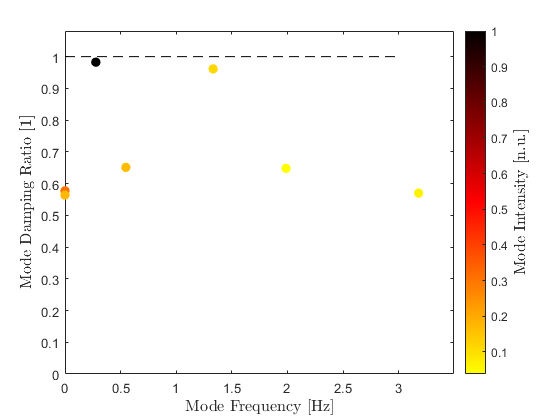


% Visualization
damFreq(dmd, norms, mags, freqs);

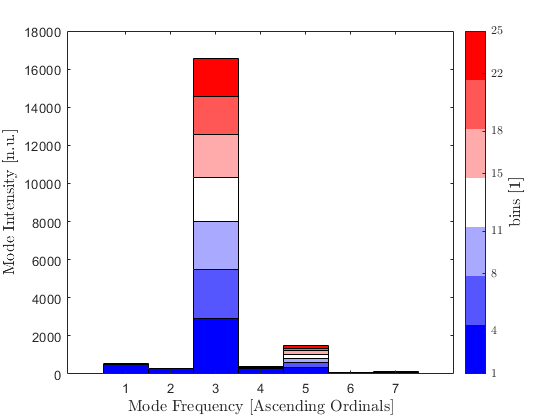

domStruct(dmd, freqs, lambda, Phi, b, predHor);

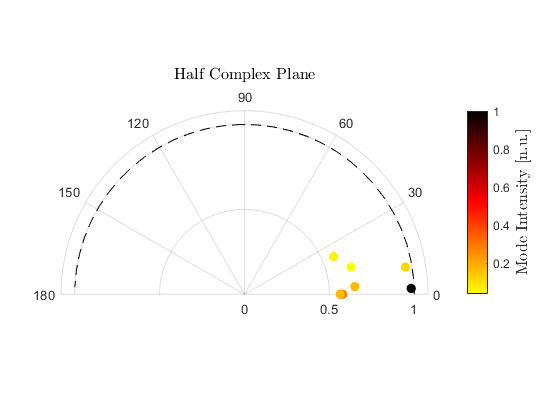

nyqPlot(dmd, norms, freqs, mags, lambda);

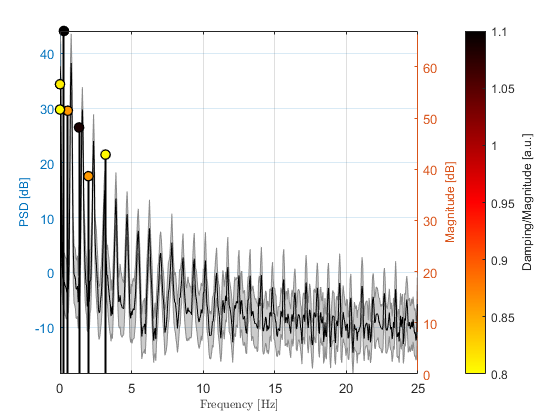

powSpect(dmd, X, freqs, norms, mags, fs);

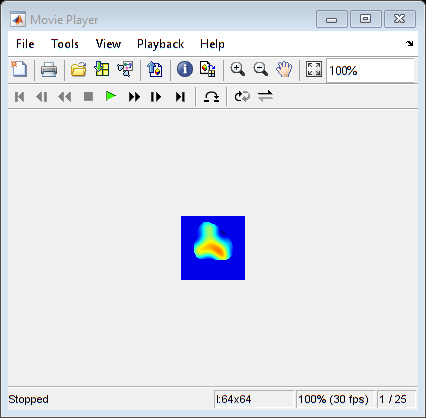

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),res,res,[]));

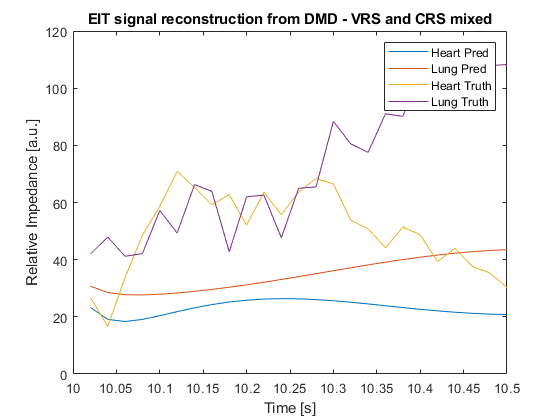

img = real(reshape(Xtotal,res,res,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");

#### Filter DMD Modes

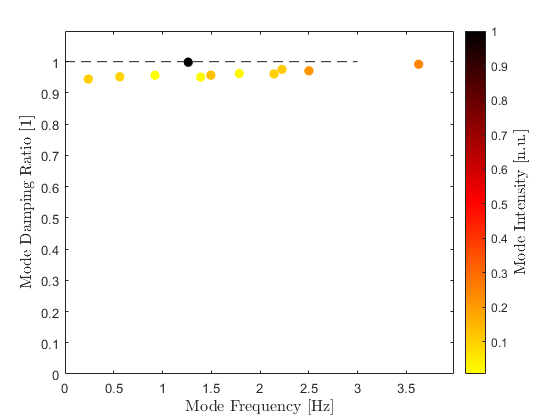

freqLims = [0.1,5];
damLims = [0.9,1.1];
magLims = [0, 1];

[norms, mags, freqs, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, lambda, omega, Phi, b, magLims, damLims, freqLims);

% Visualization
damFreq(dmd, norms, mags, freqs);

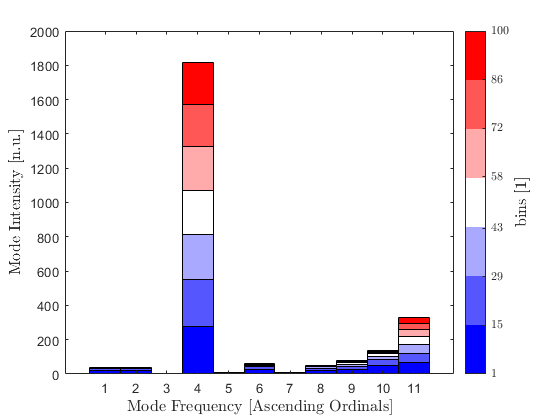

domStruct(dmd, freqs, lambda, Phi, b, predHor);

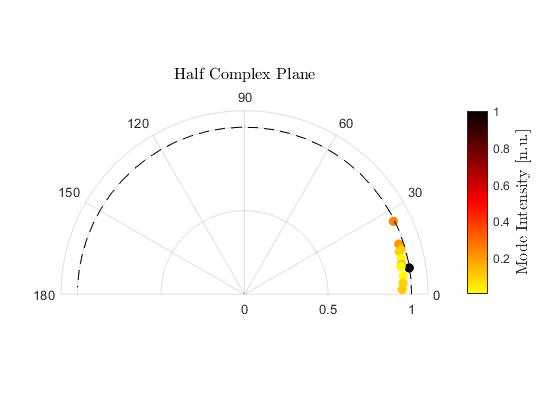

nyqPlot(dmd, norms, freqs, mags, lambda);

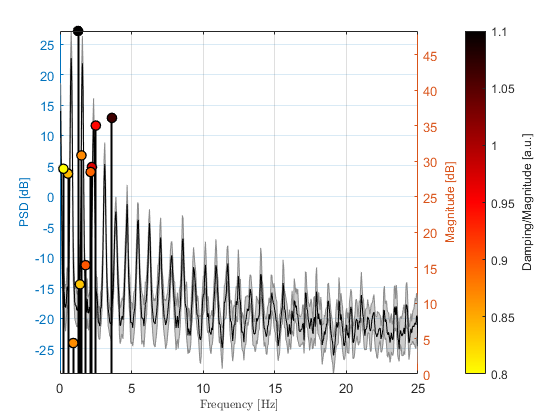

powSpect(dmd, X, freqs, norms, mags, fs);

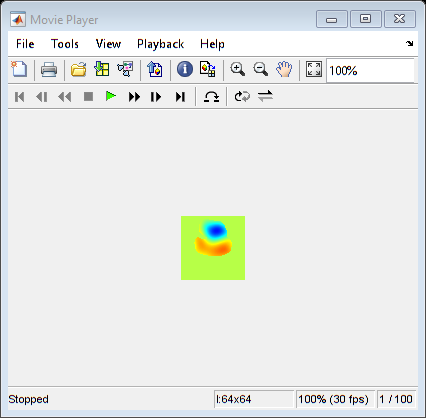

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),res,res,[]));

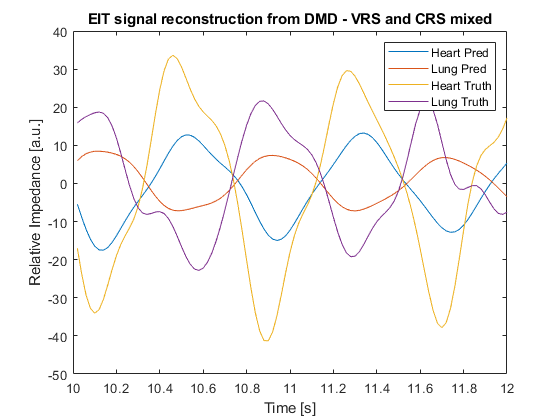

img = real(reshape(Xtotal,res,res,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");

#### Compressed Sensing DMD - get good results more than twice as fast

% Compressed Modified Exact DMD
m = 128; % number of pixels to consider
projType = 2;

tic
[cX, cY, C] = compressData(dmd, X, Y, m, projType);
[Ur, Sr, Vr, Atilde] = fitKoopman(dmd, cX, cY, rank, predHor);
[lambda, omega, Phi, b] = fitModes(dmd, Ur, Sr, Vr, Atilde, cX, cY, fs, 'exact-mod', X, Y);
[lambda, omega, Phi, b, ~] = cleanModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs] = interpModes(dmd, lambda, omega, Phi, b);
toc

Elapsed time is 0.063749 seconds.


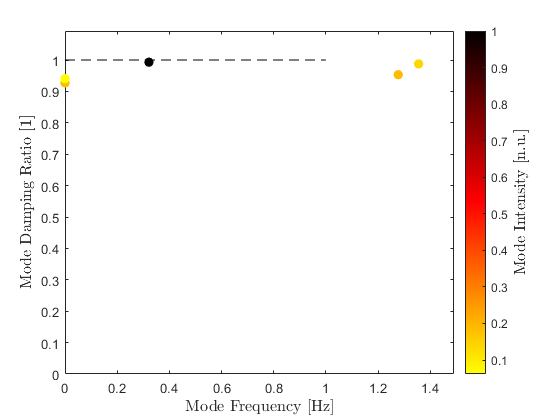


% Visualization
damFreq(dmd, norms, mags, freqs);

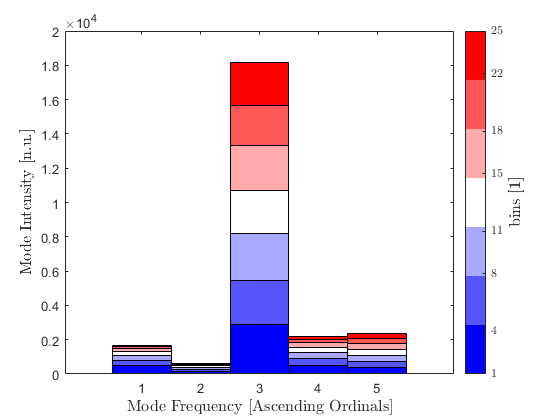

domStruct(dmd, freqs, lambda, Phi, b, predHor);

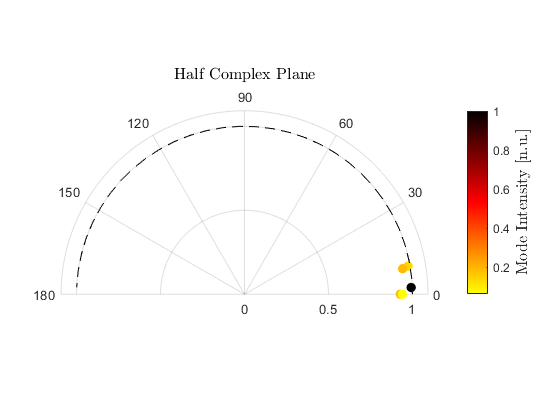

nyqPlot(dmd, norms, freqs, mags, lambda);

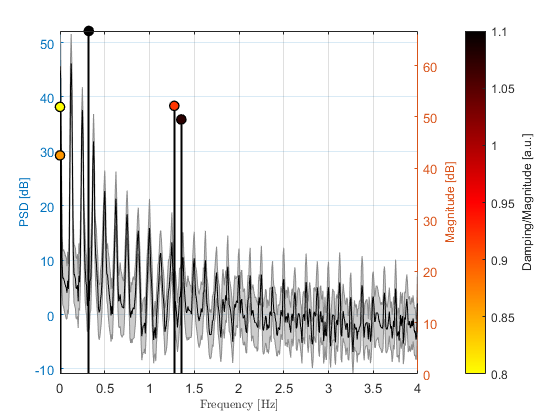

powSpect(dmd, X, freqs, norms, mags, rank);

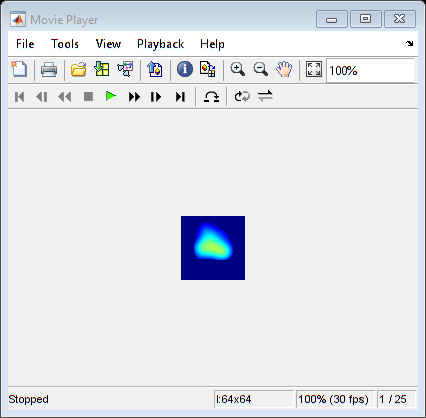

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),res,res,[]));

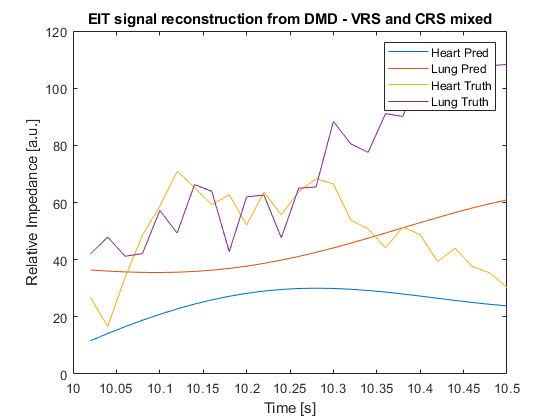

img = real(reshape(Xtotal,res,res,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");

#### Filter DMD Modes

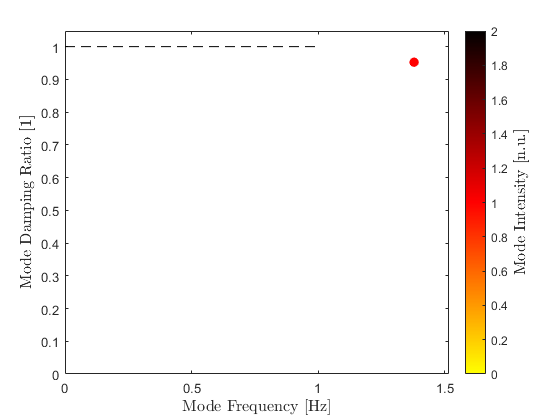

freqLims = [0.1,10];
damLims = [0.9,1.1];
magLims = [0, 1];

[norms, mags, freqs, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, lambda, omega, Phi, b, magLims, damLims, freqLims);

% Visualization
damFreq(dmd, norms, mags, freqs);

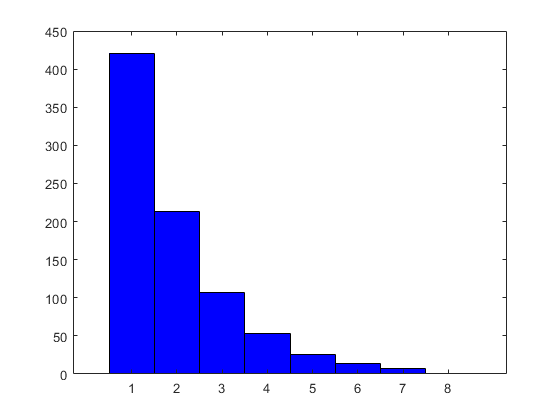

Unrecognized property 'CData' for class 'matlab.graphics.GraphicsPlaceholder'.

Error in DMD/domStruct (line 214)
                ba(i).CData = cm(i,:);

domStruct(dmd, freqs, lambda, Phi, b, predHor);

nyqPlot(dmd, norms, freqs, mags, lambda);
powSpect(dmd, X, freqs, norms, mags, fs);

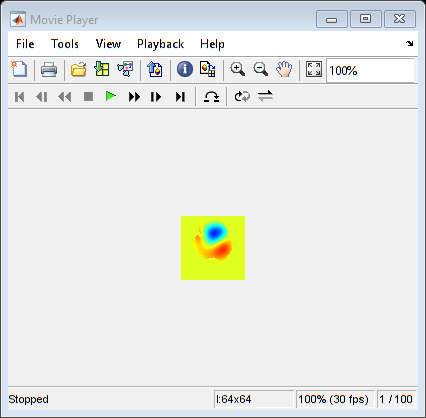

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),res,res,[]));

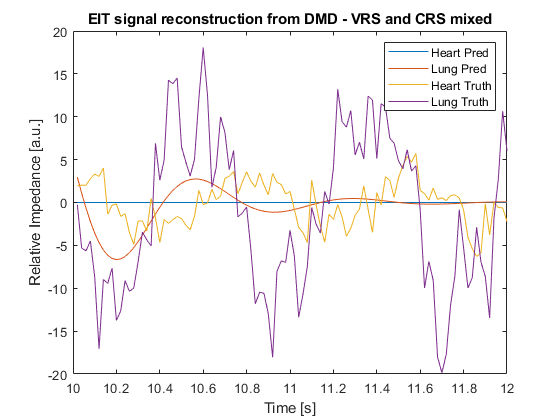

img = real(reshape(Xtotal,res,res,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");

#### Multi-Resolution DMD (has filtering incorporated)

% Compressed Multi-Resolution DMD
% Set desired ranges for frequency, norm (or damping factor), and magnitude
nLevels = 1;
freqLims = [0.1,10];
damLims = [0.9,1];
magLims = [0, 1];

tic
[lambda, omega, Phi, b] = mrFit(dmd, X, Y, rank, nLevels, predHor);

[norms, mags, freqs] = interpModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, ...
                                                                                    lambda, omega, Phi, b, ....
                                                                                    magLims, damLims, freqLims);

toc

Elapsed time is 0.014142 seconds.


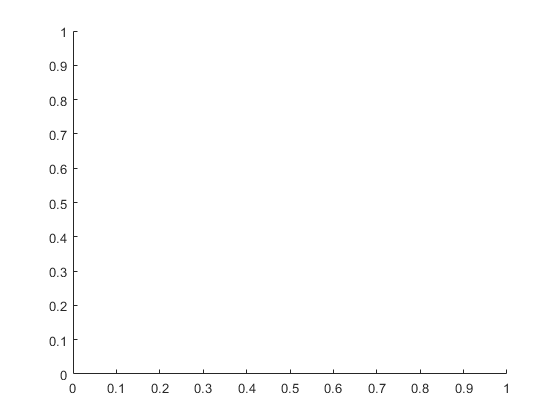

Error using scatter (line 110)
CData must be an RGB triplet, an M-by-1 vector of the same length as X, or an M-by-3 matrix.

Error in DMD/damFreq (line 179)
            scatter(freqs, mags, 50 * ones(size(freqs)), norms, 'filled', 'Marker','o');

% Visualization
damFreq(dmd, norms, mags, freqs);

domStruct(dmd, freqs, lambda, Phi, b, predHor);
nyqPlot(dmd, norms, freqs, mags, lambda);
powSpect(dmd, X, freqs, norms, mags, fs);

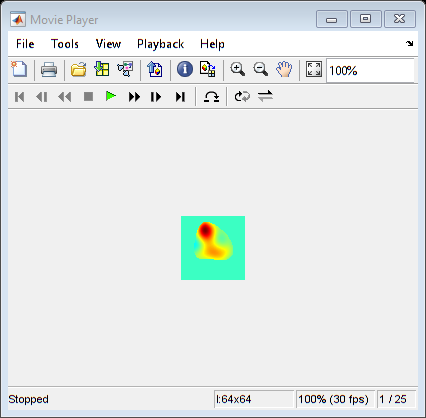

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),res,res,[]));

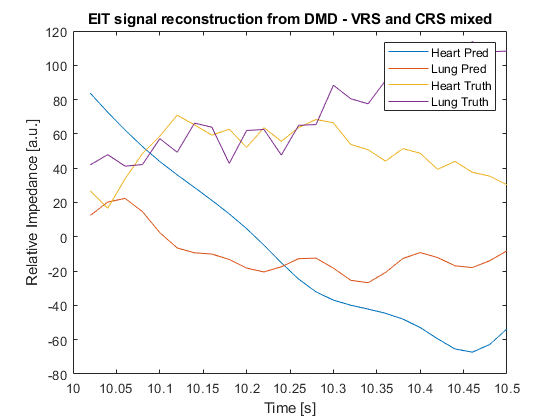

img = real(reshape(Xtotal,res,res,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");

#### Compressed Multi-Resolution DMD

% Compressed Multi-Resolution DMD
% Set desired ranges for frequency, norm (or damping factor), and magnitude
nLevels = 5;
freqLims = [0.1,10];
damLims = [0.9,1];
magLims = [0, 1];

% Compress data
[cX, cY, ~] = compressData(dmd, X, Y, 128, 2);

tic
[lambda, omega, Phi, b] = mrFit(dmd, cX, cY, rank, nLevels, predHor, X, Y);

Index in position 2 exceeds array bounds (must not exceed 1).

Error in DMD/fitModes (line 99)
                    b = inv(D) / Phi * X(:,2);

Error in DMD/mrFit (line 317)
                        [lambda, omega, Phi, b] = fitModes(obj, Ur, Sr, Vr, Atilde, x, y, 50, 'exact-mod', fx, fy);


[norms, mags, freqs] = interpModes(dmd, lambda, omega, Phi, b);
[norms, mags, freqs, lambda, omega, Phi, b] = boxSelection(dmd, norms, mags, freqs, ...
                                                                                    lambda, omega, Phi, b, ....
                                                                                    magLims, damLims, freqLims);

toc

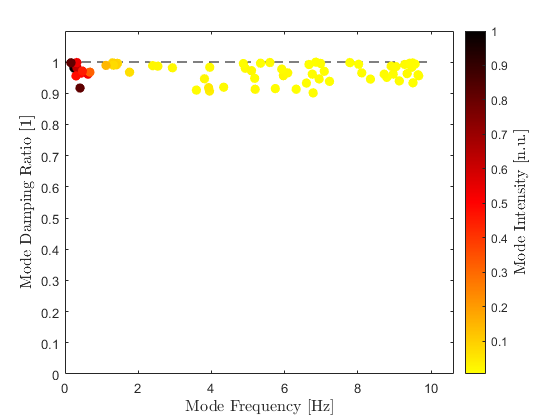

% Visualization
damFreq(dmd, norms, mags, freqs);

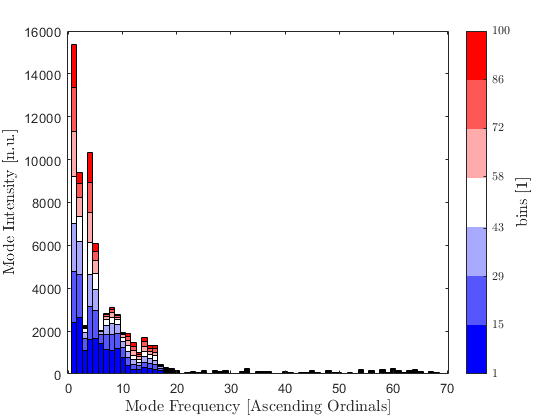

domStruct(dmd, freqs, lambda, Phi, b, predHor);

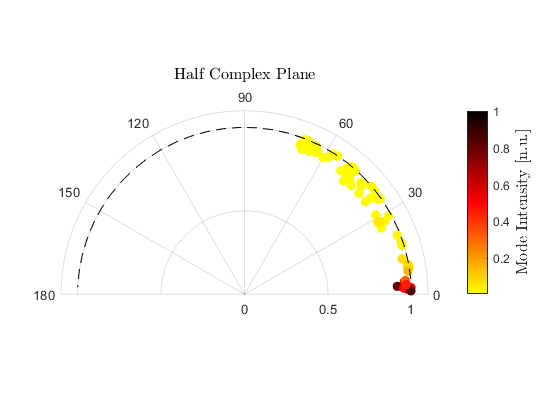

nyqPlot(dmd, norms, freqs, mags, lambda);

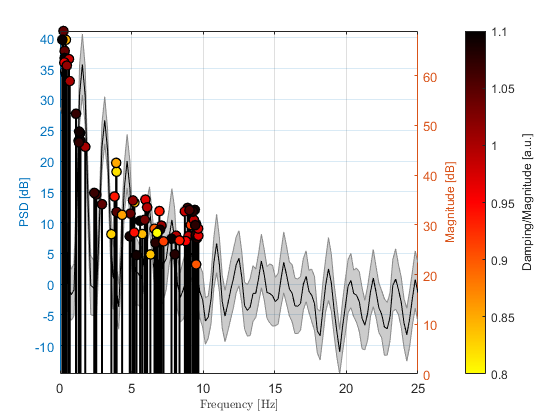

powSpect(dmd, X, freqs, norms, mags, fs);

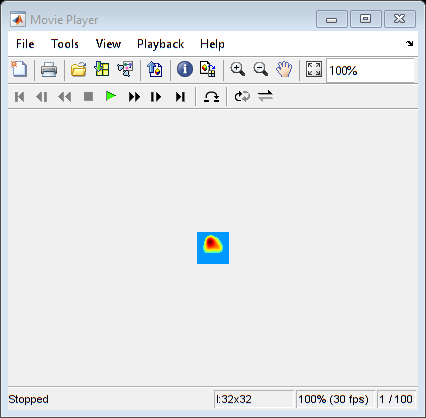

[Xcomps, Xtotal] = reconData(dmd, lambda, omega, Phi, b, predHor, fs, 'cont');
playVideo(reshape(real(Xtotal),res,res,[]));

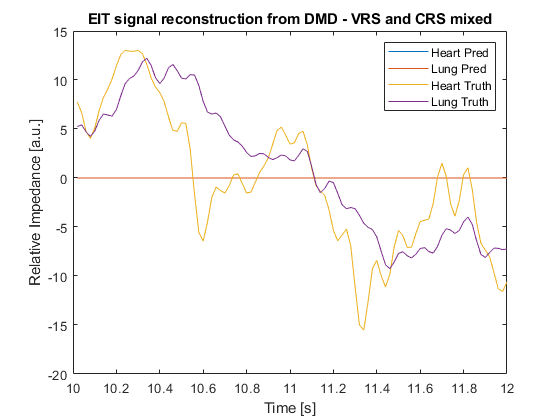

img = real(reshape(Xtotal,res,res,predHor));

heartSigRecon = squeeze(img(heartPix(1),heartPix(2),:));
lungSigRecon = squeeze(img(lungPix(1),lungPix(2),:));

% Select heart and lung pixels
img = imgV2(:,:,xStart + 1:xStart + predHor);

heartSigTruth = squeeze(img(heartPix(1),heartPix(2),:));
lungSigTruth = squeeze(img(lungPix(1),lungPix(2),:));

figure; plot(tSim, [heartSigRecon,lungSigRecon,heartSigTruth,lungSigTruth]);
xlabel('Time [s]'); ylabel('Relative Impedance [a.u.]');
legend(["Heart Pred","Lung Pred","Heart Truth", "Lung Truth"]);
title("EIT signal reconstruction from DMD - VRS and CRS mixed");